load_parameters

t_end = 0.1;
t = 0 : t_step : t_end;

f_0 = f_sampling / 10;
Q = 1e3;
bandwidth = f_0 / Q

band = [f_0 - 10*bandwidth, f_0 + 10*bandwidth]

wo = f_0 / (f_sampling/2)
bw = bandwidth / (f_sampling/2)

x = randn(size(t))

y1 = resonator(x, f_0, f_0*ones(size(t)), Q, f_sampling);

display_spectra(x, y1, f_sampling, band);

[b, a] = iirpeak(wo, bw)
y2 = filter(b, a, x);

display_spectra(x, y2, f_sampling, band);

[b, a] = my_iirpeak(f_0, Q, f_sampling);
y2 = filter(b, a, x);

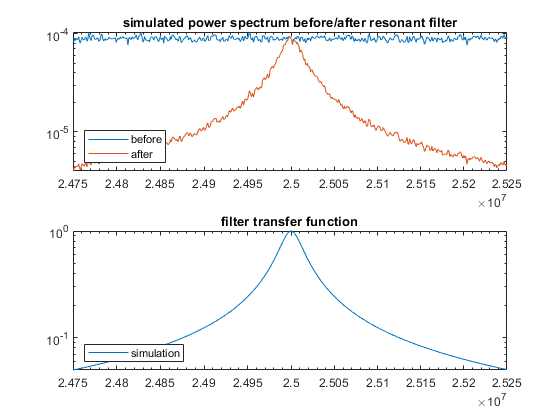

display_spectra(x, y2, f_sampling, band);

y3 = zeros(size(t));
state = resonator_setup();
for i = 1 : length(t)
    [state, y] = resonator_step(state, x(i), f_0, Q, f_sampling);
    y3(i) = y;
end

display_spectra(x, y3, f_sampling, band);

% timing

r1 = @() resonator(x, f_0, f_0*ones(size(t)), Q, f_sampling);
r2 = @() resonator_2(x, f_0, f_0*ones(size(t)), Q, f_sampling);

timeit(r1)

ans = 5.2056

timeit(r2)

ans = 6.0093